# SLCO4A - Aula Prática 13

## Função de transferência

Um sistema LTI é completamente descrito por uma equação diferencial com coeficientes constantes ($a_n$ e $b_m$), ou seja, por uma equação diferencial de $n-$ésima ordem da forma

$a_n \frac{d^n y\left(t\right)}{{\textrm{dt}}^n }+\cdots +a_1 \frac{dy\left(t\right)}{\textrm{dt}}+a_0 y\left(t\right)=b_m \frac{d^m x\left(t\right)}{{\textrm{dt}}^m }+\cdots +b_1 \frac{d\;x\left(t\right)}{\textrm{dt}}+b_0 x\left(t\right)$.

Aplicando transformada de Laplace de ambos lados da equação e considerando condições iniciais nulas, obtém-se


$$a_n s^n Y\left(s\right)+a_{n-1} s^{n-1} Y\left(s\right)+\cdots +a_0 Y\left(s\right)=b_m s^m X\left(s\right)+b_{n-1} s^{n-1} X\left(s\right)+\cdots +a_0 X\left(s\right)$$


Readequando para a forma de função de transferência $\frac{Y\left(s\right)}{H\left(s\right)}$


$$H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}=\frac{b_m s^m +b_{m-1} s^{m-1} +\cdots +b_0 }{a_n s^n +a_{n-1} s^{n-1} +\cdots +a_0 }$$


$H\left(s\right)$é chamada função de transferência e é uma descrição completa de um sistema LTI. 

Uma visão alternativa de função transferência é cosiderar a resposta temporal de saída de um sistema, no qual


$$y\left(t\right)=h\left(t\right)*x\left(t\right)$$


Aplicando a transformada de Laplace de ambos lados, obtém-se


$$Y\left(s\right)=H\left(s\right)X\left(s\right)$$


ou ainda $H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}$

onde $H\left(s\right)=L\left\lbrace h\left(t\right)\right\rbrace$. Portanto, a função de transferência de um sistema é a transformada de Laplace da resposta impulsiva do sistema.

**Exercício 1**: Compute a função de transferência $H\left(s\right)$ do sistema descrito pela resposta impulsiva $h\left(t\right)={\textrm{te}}^{-t} u\left(t\right)$

syms t s 
h = t*exp(-t)*heaviside(t);
H = laplace(h, s)

$$H = \frac{1}{{\left(s+1\right)}^{2}}$$

**Exercício 2**: Compute a função de transferência do sistema descrito pelas equação diferencial:

$y^{\prime \prime } \left(t\right)+3y^{\prime } \left(t\right)-2y\left(t\right)=x^{\prime \prime } \left(t\right)-x^{\prime } \left(t\right)-6x\left(t\right)$, considerando condições iniciais nulas.

syms t s Y X 
G = s^2*Y + 3*s*Y - 2*Y - s^2*X + s*X + 6*X;
Y = solve(G, Y);
H = simplify(Y/X)

$$H = -\frac{-s^{2}+s+6}{s^{2}+3\,s-2}$$

### Comando tf

As funções de transferência é usualmente dada na forma racional, escrita na forma de dois polinômios


$$H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}=\frac{b_m s^m +b_{m-1} s^{m-1} +\cdots +b_0 }{a_n s^n +a_{n-1} s^{n-1} +\cdots +a_0 }$$


Para definir uma função de transferência pode-se utilizar a função `tf,` cuja sintaxe é dada por:

**Exercício 3: **Crie a função de transferência $H\left(s\right)=\frac{s^2 }{s^2 +s+1}$

num = [1 0 0];
den = [1 1 1];
H = tf(num, den)

H =
 
      s^2
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



**Exercício 4: **Um sistema é descrito pela seguinte função de transferência $H\left(s\right)=\frac{s+2}{s^2 +3s+1}$

Determine a função de transferência do sistema no qual ocorra um atraso temporal de 2 segundos na resposta temporal do sistema.

num = [1 2];
den = [1 3 1];
H = tf(num, den)

H =
 
      s + 2
  -------------
  s^2 + 3 s + 1
 
Continuous-time transfer function.



H_atraso = tf(num, den, 'inputdelay', 2)

H_atraso =
 
                  s + 2
  exp(-2*s) * -------------
              s^2 + 3 s + 1
 
Continuous-time transfer function.



**Exercício 5: **Compute e plot a resposta impulsiva $h_1 \left(t\right)$ e $h_2 \left(t\right)$dos sistemas com funções de transferência sejam 

$H_1 \left(s\right)=\frac{s}{\left(s^2 +4\right)}$ e $H_2 \left(s\right)=\frac{s}{\left(s^2 +4\right)}e^{-3s}$, respectivamente.

syms t s 
H1 = s/(s^2 + 4);
h1 = ilaplace(H1, t)

$$h1 = \cos\left(2\,t\right)$$

figure 
fplot(h1, [0 20])
hold on
H2 = exp(-3*s) * H1;
h2 = ilaplace(H2, t)

$$h2 = \mathrm{heaviside}\left(t-3\right)\,\cos\left(2\,t-6\right)$$

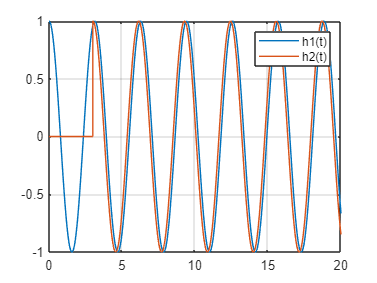

fplot(h2, [0 20])
grid on
legend('h1(t)', 'h2(t)')

## Estabilidade de sistemas contínuos

Um critério para defiir estabilidade de um sistema é o *bounded-input bounded output (BIBO)* se a resposta impulsiva do sistema é absolutamente integrável. A expressão matemática é 


$$\int_{-\infty \;}^{\infty } \left|h\left(t\right)\right|\mathrm{dt}<\infty$$


Um critério alternativo em relação ao BIBO estabilidade pode ser considerado a partir da avaliação dos polos:

*Se ****todos os polos**** de uma funçaõ de transferência estão localizados no ****semiplano esquerdo**** do plano complexo, o sistema é BIBO ****estável.***

*Equivalentemente, se a parte real de todos os polos são negativas, o sistema é BIBO estável.*

*Se um polo está no semiplano direito do plano complexo (equivalentemente tem parte real positiva), então o sistema é instável. *

**Exercício 6: **Dada a função de transferência de um sistema


$$H\left(s\right)=\frac{3s^2 +5}{s^3 +3s^2 +6s+4}$$
 

a) Determine se o sistema é estável.

den = [1 3 6 4];
polos = roots(den)

polos =   -1.0000 + 1.7321i
  -1.0000 - 1.7321i
  -1.0000 + 0.0000i


figure 
plot(real(polos), imag(polos),  'x')
grid on
xlim([-2 2])

b) Plot os polos e zeros

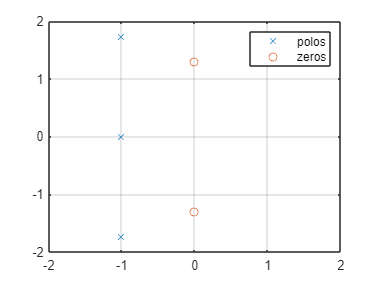

num = [3 0 5];
zeros = roots(num);
hold on
plot(real(zeros), imag(zeros), 'o')
legend('polos', 'zeros')

c) Plot os polos e zeros utilizando comandos `tf, pzmap`

H = tf(num, den)

H =
 
        3 s^2 + 5
  ---------------------
  s^3 + 3 s^2 + 6 s + 4
 
Continuous-time transfer function.



polos = pole(H)

polos =   -1.0000 + 1.7321i
  -1.0000 - 1.7321i
  -1.0000 + 0.0000i


zeros = zero(H)

zeros =    0.0000 + 1.2910i
   0.0000 - 1.2910i


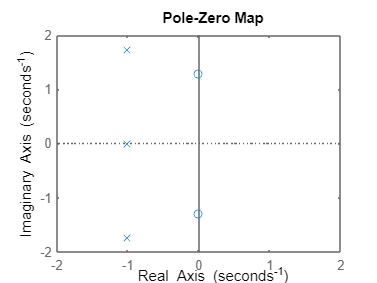

figure 
pzmap(H)
xlim([-2 2])

## Função de transferência na forma zero, polo e ganho

A função de transferência de um sistema SISO pode ser escrito na forma


$$H\left(s\right)=K\frac{\left(s-z_1 \right)\left(s-z_2 \right)\cdots \left(s-z_m \right)}{\left(s-p_1 \right)\left(s-p_2 \right)\cdots \left(s-p_n \right)}$$


onde $z_m$ são os zeros do sistema, $p_n$ são os polos do sistema e $K$ é o ganho do sistema. 

**Exercício 7: **Expresse a função de transferência na forma de zeros, polos e ganho


$$H\left(s\right)=\frac{2s+1}{s^2 +3s+2}$$
 

H = tf([2 1], [1 3 2])

H =
 
     2 s + 1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



Hzpk = zpk(H)

Hzpk =
 
   2 (s+0.5)
  -----------
  (s+2) (s+1)
 
Continuous-time zero/pole/gain model.



## Interconexão de sistemas

**Exercício 8: **A função de transferência do subsistema $S_1$ é $H_1 \left(s\right)=\frac{s+1}{500s^2 }$ e do subsistema $S_2$ é $H_2 \left(s\right)=\frac{s+1}{s+2}$

Calcule a função de transferência $H\left(s\right)$ total do sistema para os casos de conexão em cascata, paralelo, e realimentado (*feedback*).

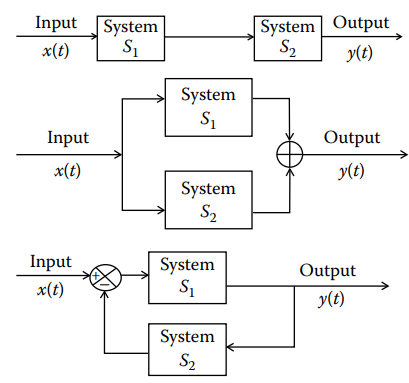

a) subsistemas em série (cascata).

num1 = [1 1];
den1 = [500 0 0];
H1 = tf(num1, den1)

H1 =
 
   s + 1
  -------
  500 s^2
 
Continuous-time transfer function.



num2 = [1 1];
den2 = [1 2];
H2 = tf(num2, den2)

H2 =
 
  s + 1
  -----
  s + 2
 
Continuous-time transfer function.




Hs = series(H1, H2)

Hs =
 
    s^2 + 2 s + 1
  ------------------
  500 s^3 + 1000 s^2
 
Continuous-time transfer function.



b) subsistemas em paralelo.

Hp = parallel(H1, H2)

Hp =
 
  500 s^3 + 501 s^2 + 3 s + 2
  ---------------------------
      500 s^3 + 1000 s^2
 
Continuous-time transfer function.



c) subsistemas com realimentação.

Hr = feedback(H1, H2)

Hr =
 
         s^2 + 3 s + 2
  ----------------------------
  500 s^3 + 1001 s^2 + 2 s + 1
 
Continuous-time transfer function.



## Resposta temporal de sistemas contínuos

**Exercício 9: **Um sistema é especificado pela seguinte função de transferência $H\left(s\right)=\frac{10}{s^2 +2s+10}$

**a)** Compute e plote a resposta temporal de saída do sistema $y\left(t\right)$para um sinal de entrada $x\left(t\right)=\cos \left(2\pi \;t\right)$, $0\le t\le 10$.

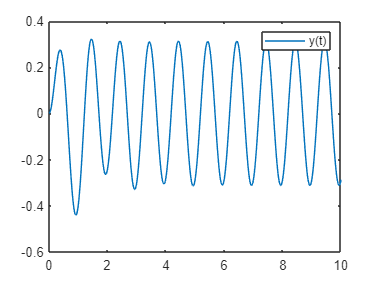

H = tf(10, [1 2 10]);
t = 0:0.01:10;
x = cos(2*pi*t);
y = lsim(H, x, t);
figure
plot(t, y)
legend('y(t)')

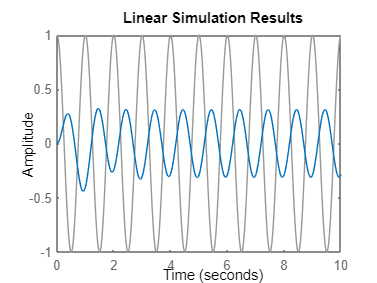


%forma alternativa 
figure 
lsim(H, x, t)

**b) **compute e plote a resposta temporal de saída do sistema $y\left(t\right)$para um sinal de entrada do tipo degrau unitário $x\left(t\right)=u\left(t\right)$, $0\le t\le 6$.

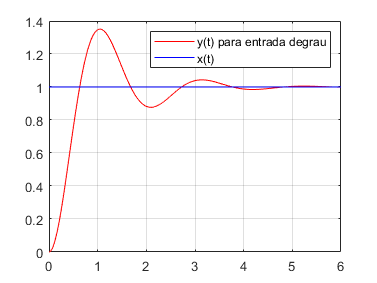

t = 0:0.01:6;
x = ones(size(t));
figure 
y = lsim(H, x, t);
plot(t, y, 'r')
hold on
plot(t, x, 'b')
legend('y(t) para entrada degrau', 'x(t)')
grid on

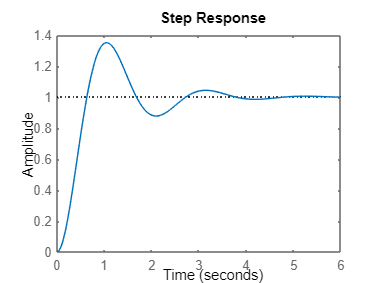

%Forma usual
figure 
step(H)

**c) **compute e plote a resposta temporal de saída do sistema $y\left(t\right)$para um sinal de entrada do tipo impulso $x\left(t\right)=\delta \left(t\right)$, $0\le t\le 6$.

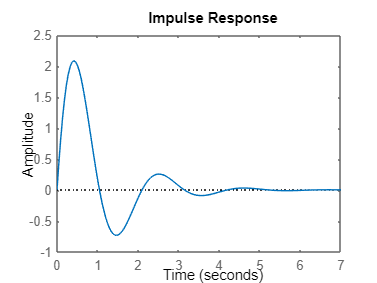

impulse(H)